# Computer vision Programming Assignment 1

## 1. Projective Image Transformation

clear; close all;

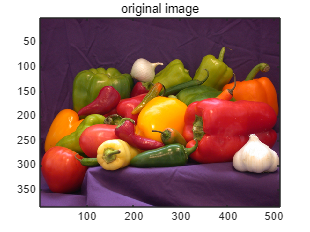

% load the image
img = imread("peppers.png");
iptsetpref("ImshowAxesVisible","on")
image(img)
title("original image")

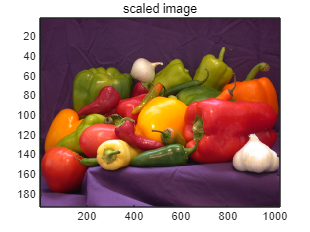

% scaling the image
Scalematrix = [2 0 0; 0 0.5 0; 0 0 1];
tform_scale = projtform2d(Scalematrix);
% projective2d()가 matlab 최신 버전에서는 권장되지 않아 복잡한 transform에 대해선
% 같은 기능을 수행하는 projtform2d()를 사용함

img_scale = imwarp(img,tform_scale);
image(img_scale)
title("scaled image")

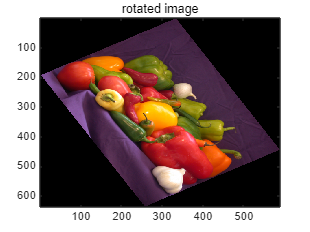

% rotate the image
Rotationmatrix = [cosd(60) -sind(60) 0; sind(60) cosd(60) 0; 0 0 1];
tform_rotation = projtform2d(Rotationmatrix);

img_rotate = imwarp(img, tform_rotation);
image(img_rotate)
title("rotated image")

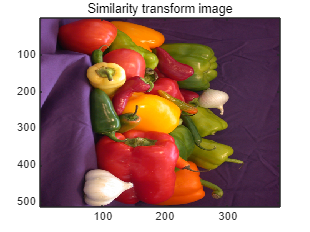

% Similarity transform
Sim_matrix = [3*cosd(90) -sind(90) 10;
              sind(90) 3*cosd(90) 20;
              0 0 1];
tform_sim = projtform2d(Sim_matrix); 

img_similarity = imwarp(img,tform_sim);
image(img_similarity)
title("Similarity transform image")

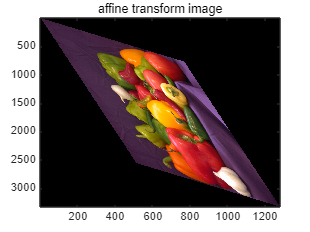

% Affine transformation
affine_matrix = [1 2 3; 5 2 4; 0 0 1];
tform_affine = projtform2d(affine_matrix);

img_affine = imwarp(img,tform_affine);
image(img_affine)
title("affine transform image")

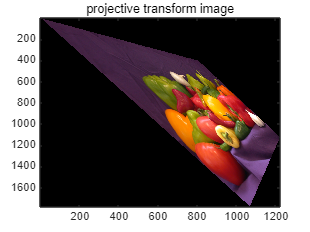

% Projective transform
projective_matrix = [4 3 1; 2 5 0; 0.003 0.0002 1];
tform_projective = projtform2d(projective_matrix);

img_proj = imwarp(img,tform_projective);
image(img_proj)
title("projective transform image")

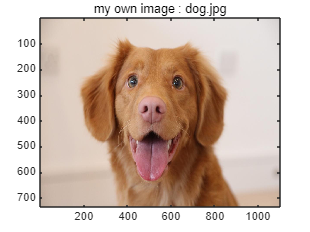

% repeat the whole process for my own image
img2 = imread("dog.jpg");
image(img2)
title("my own image : dog.jpg")

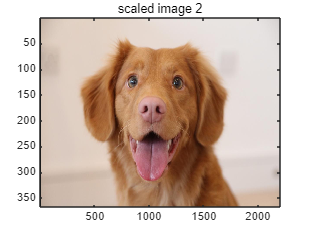


img_scale2 = imwarp(img2,tform_scale);
image(img_scale2)
title("scaled image 2")

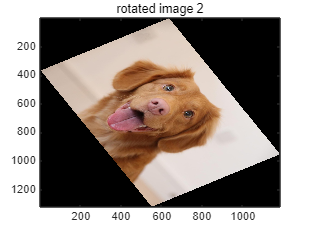


img_rotate2 = imwarp(img2, tform_rotation);
image(img_rotate2)
title("rotated image 2")

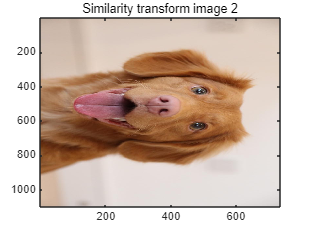


img_similarity2 = imwarp(img2,tform_sim);
image(img_similarity2)
title("Similarity transform image 2")

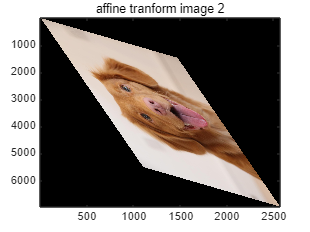


img_affine2 = imwarp(img2,tform_affine);
image(img_affine2)
title("affine tranform image 2")

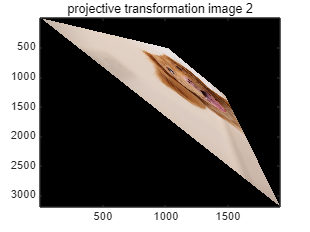


img_proj2 = imwarp(img2,tform_projective);
image(img_proj2)
title("projective transformation image 2")

## 2. Color Space

img = imread("peppers.png");
image(img)
title("original image")

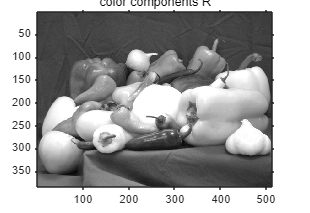

% Display color components RGB
R = img(:, :, 1);
G = img(:, :, 2);
B = img(:, :, 3);

imshow(R)
title("color components R")

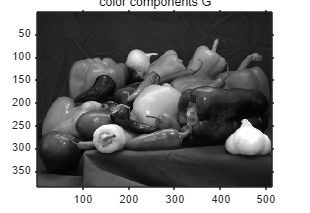

imshow(G)
title("color components G")

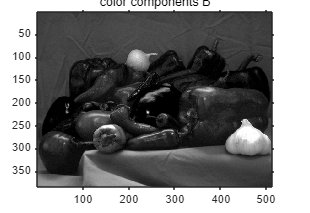

imshow(B)
title("color components B")

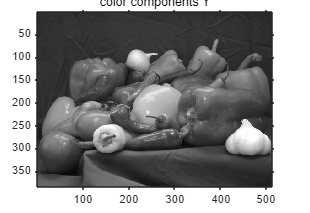

% YCbCr coordinates
function [Y,Cb,Cr] = RGB2YCbCr(R,G,B)
    Y = 0.299 * R + 0.587 * G + 0.114 * B;
    Cb = -0.168736 * R - 0.331264 * G + 0.5 * B + 128;
    Cr = 0.5 * R - 0.418688 * G - 0.081312 * B + 128;
end

[Y,Cb,Cr] = RGB2YCbCr(R,G,B);

imshow(Y)
title("color components Y")

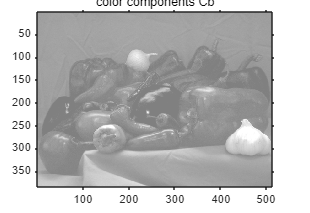

imshow(Cb)
title("color components Cb")

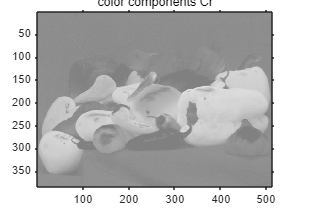

imshow(Cr)
title("color components Cr")

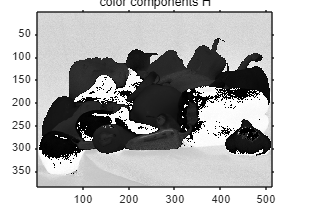

% HSI coordinates
function [H, S, I] = RGB2HSI(R,G,B)
    Rn = double(R) / 255;
    Gn = double(G) / 255;
    Bn = double(B) / 255;
    
    I = (Rn + Gn + Bn) / 3;
    
    X_min = min(min(Rn, Gn), Bn);
    S = 1 - X_min./I;
    S(I==0) = 0;
    
    X_max = max(max(Rn,Gn),Bn);
    Chroma = X_max-X_min;
    H = zeros(size(Rn));
    for i = 1:size(H,1)
        for j = 1:size(H,2)
            M = X_max(i,j);
            m = X_min(i,j);
            c = Chroma(i,j); 
            r = Rn(i,j);
            g = Gn(i,j);
            b = Bn(i,j);
    
            if M == r
                H(i,j) = mod((g-b)/c,6);
            elseif M == g
                H(i,j) = (b-r)/c + 2;
            elseif M == b
                H(i,j) = (r-g)/c + 4;
            else
                H(i,j) = 0;
            end
        end
    end
    H = H/6;
end

[H, S, I] = RGB2HSI(R,G,B);

imshow(H)
title("color components H")

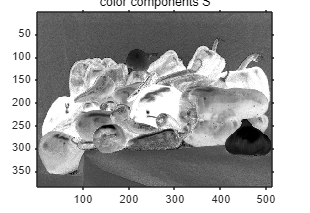

imshow(S)
title("color components S")

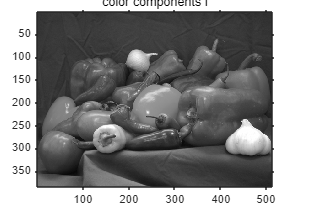

imshow(I)
title("color components I")

% HSI to RGB
function [R, G, B, newimg] = HSI2RGB(H, S, I)
    R = zeros(size(H));
    G = zeros(size(H));
    B = zeros(size(H));
    newimg = zeros(size(H,1),size(H,2),3);
    
    H = H*6;
    Z = 1 - abs(mod(H,2)-1);
    C = 3.*I.*S./(1+Z);
    X = C.*Z;
    m = I.*(1 - S);
    
    for j = 1:size(H,1)
        for k = 1:size(H,2)
            h = H(j,k);
            s = S(j,k);
            i = I(j,k);
            c = C(j,k);
            x = X(j,k);

            if h >= 0 & h < 1 
                R(j,k) = c;
                G(j,k) = x;
                B(j,k) = 0;
            elseif h >= 1 & h < 2 
                R(j,k) = x;
                G(j,k) = c;
                B(j,k) = 0;
            elseif h >= 2 & h < 3 
                R(j,k) = 0;
                G(j,k) = c;
                B(j,k) = x;
            elseif h >= 3 & h < 4 
                R(j,k) = 0;
                G(j,k) = x;
                B(j,k) = c;
            elseif h >= 4 & h < 5 
                R(j,k) = x;
                G(j,k) = 0;
                B(j,k) = c;
            elseif h >= 5 & h < 6 
                R(j,k) = c;
                G(j,k) = 0;
                B(j,k) = x;
            else
                R(j,k) = 0;
                G(j,k) = 0;
                B(j,k) = 0;
            end

            R(j,k) = R(j,k) + m(j,k);
            G(j,k) = G(j,k) + m(j,k);
            B(j,k) = B(j,k) + m(j,k);
        end
    end
    newimg(:,:,1) = R;
    newimg(:,:,2) = G;
    newimg(:,:,3) = B;
end

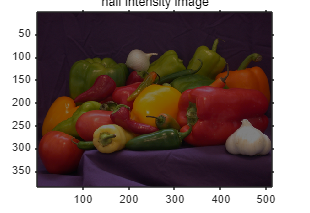

% manipulate I
I2 = I/2;
[~, ~, ~, img_I2] = HSI2RGB(H, S, I2);
imshow(img_I2)
title("half intensity image")

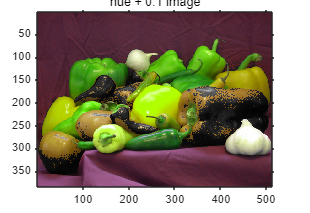


% manipulate H
H2 = H + 0.1;
[~, ~, ~, img_H2] = HSI2RGB(H2, S, I);
imshow(img_H2)
title("hue + 0.1 image")

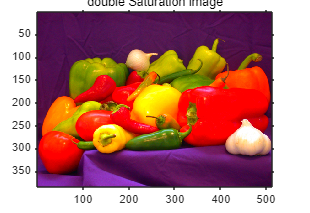


% manipulate S
S2 = 2*S;
[~, ~, ~, img_S2] = HSI2RGB(H, S2, I);
imshow(img_S2)
title("double Saturation image")

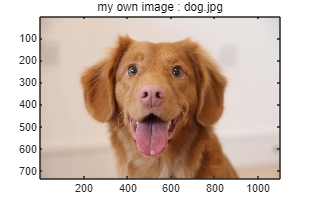

img_dog = imread("dog.jpg");
image(img_dog)
title("my own image : dog.jpg")

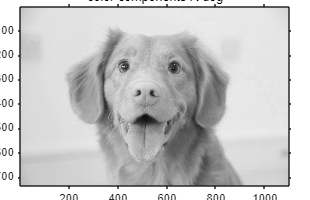


R_dog = img_dog(:, :, 1);
G_dog = img_dog(:, :, 2);
B_dog = img_dog(:, :, 3);

imshow(R_dog)
title("color components R dog")

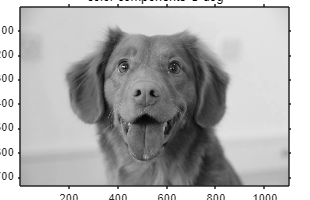

imshow(G_dog)
title("color components G dog")

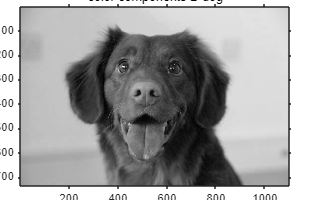

imshow(B_dog)
title("color components B dog")

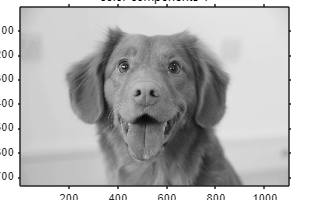



[Y_dog,Cb_dog,Cr_dog] = RGB2YCbCr(R_dog,G_dog,B_dog);

imshow(Y_dog)
title("color components Y")

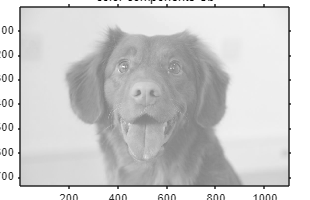

imshow(Cb_dog)
title("color components Cb")

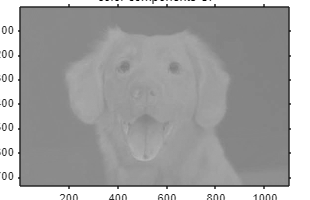

imshow(Cr_dog)
title("color components Cr")

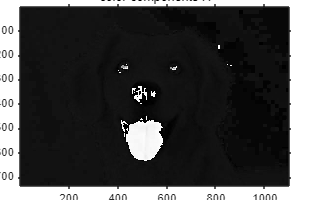


[H_dog, S_dog, I_dog] = RGB2HSI(R_dog,G_dog,B_dog);

imshow(H_dog)
title("color components H")

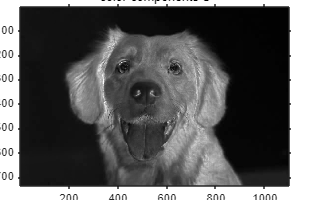

imshow(S_dog)
title("color components S")

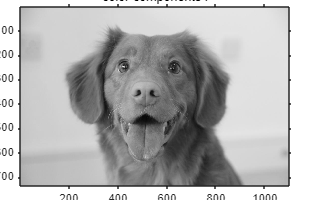

imshow(I_dog)
title("color components I")

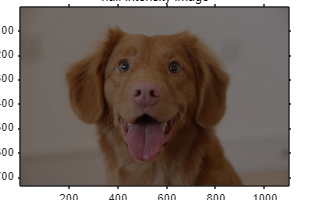


% I
I3 = I_dog/2;
[~, ~, ~, img_I3] = HSI2RGB(H_dog, S_dog, I3);
imshow(img_I3)
title("half intensity image")

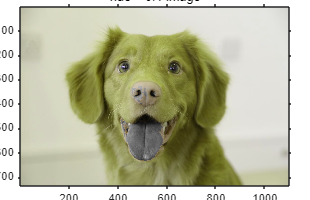


% H
H3 = H_dog + 0.1;
[~, ~, ~, img_H3] = HSI2RGB(H3, S_dog, I_dog);
imshow(img_H3)
title("hue + 0.1 image")

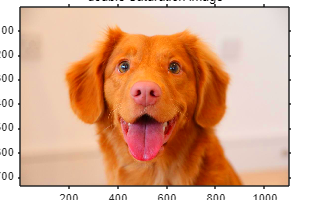


% S
S3 = 2*S_dog;
[~, ~, ~, img_S3] = HSI2RGB(H_dog, S3, I_dog);
imshow(img_S3)
title("double Saturation image")